% Define the root path of your project
rootPath = pwd;

addpath(genpath(fullfile(rootPath, 'functions')));

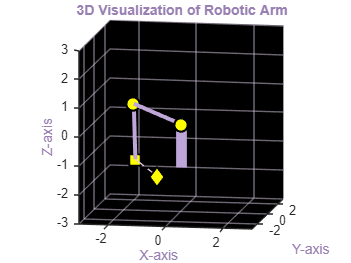

clear;
clf;
clc;

% Calculate end effector position and obtain arm configurations
[pGripper, arm1, arm2, arm3] = EndEffectorPosition(30, 45, 2);

% Plot the robotic arm system
plotSystem(arm1, arm2, arm3);

% Set the view angle for the plot
view(10, 10);

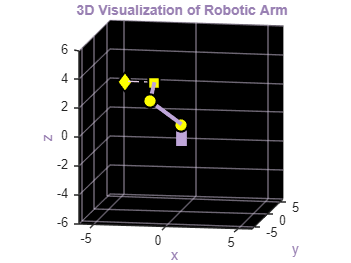

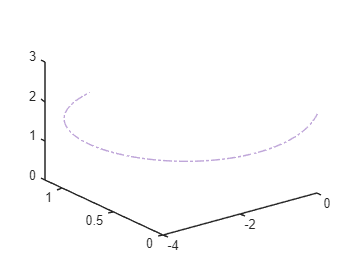


thetaStart = [0, 0, 0];      % Initial angles [Q1_start, Q2_start] in radians
thetaStop = [pi/6, pi, 2];   % Final   angles [Q1_end, Q2_end]     in radians
animationTime = 10;          % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);

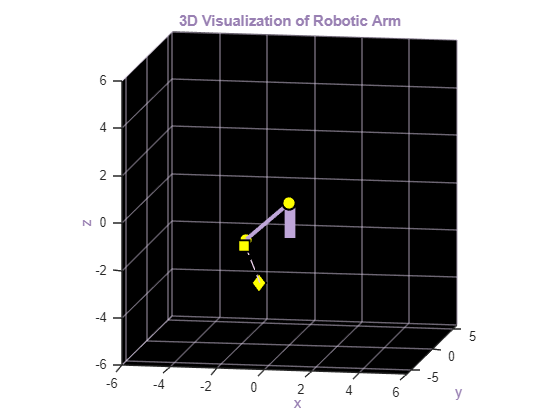

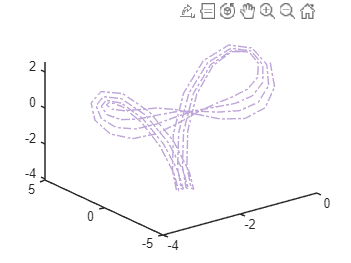


thetaStart = [-8 * pi, -8 * pi/2, -1];   % Initial angles [Q1_start, Q2_start] in radians
thetaStop = [8 * pi, 8 * pi/2, 1];       % Final   angles [Q1_end, Q2_end]     in radians
animationTime = 10;                      % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);

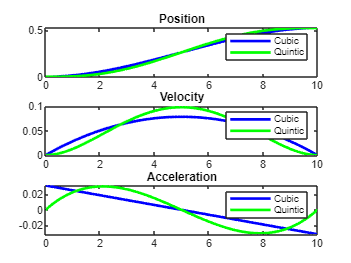

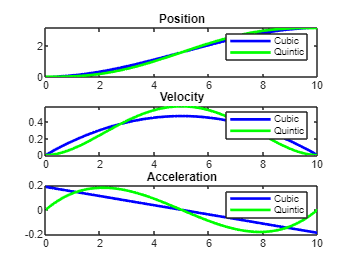

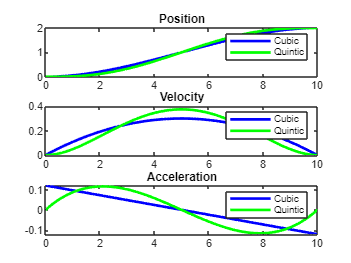


q=[0, pi/6;...
   0, pi;...
   0, 2]; 
    

T = 10;        % Timpul total pentru traiectorie (de exemplu 5 secunde)
n = 100;      % Numărul de pași (100 de puncte pentru traiectorie)


% Apelarea funcției care calculează traiectoria
% Functia va returna pozitiile, viteza si acceleratia pentru fiecare cuplu de roti

trajectoryPlanner(q, T, n);

Current plot held


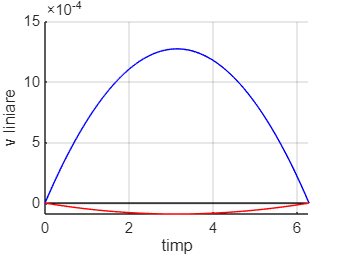

Current plot held


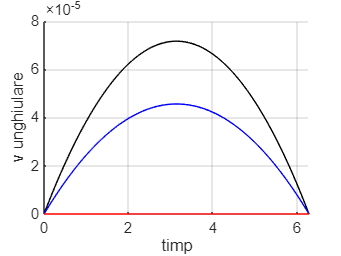

ans =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013   

[Q, dQ, ddQ] = CubicTrajectory(q, T, n);

%%negru este viteza pe x,
% albastru y
% rosu z
timp=linspace(0,2*pi,n);
%%cinematicadirecta_Jacobian(Q,dQ,timp,1)
DirectKinematics(Q,dQ,timp,1)

%%vitezele liniare/unghiulare
